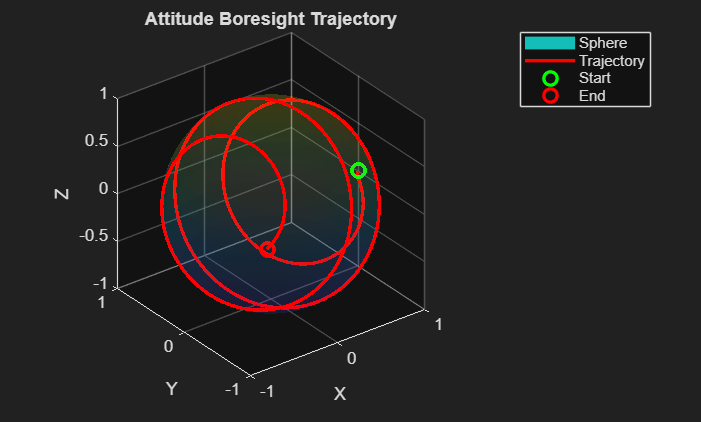

% --- Unit sphere for reference ---
figure;
set(gcf,'Visible','on')

[Xs, Ys, Zs] = sphere(40);
surf(Xs, Ys, Zs, 'FaceAlpha', 0.1, 'EdgeColor', 'none');
axis equal;
hold on;
xlabel('X'); ylabel('Y'); zlabel('Z');
title('Attitude Boresight Trajectory');

% --- Initialize storage ---
N = size(q,1);
traj = zeros(N,3);

% --- Compute boresight over time ---
for k = 1:N
    R = quat2rotm(q(k,:));
    v = R * [1;0;0];   % camera boresight
    traj(k,:) = v';
end

% --- Plot trajectory ---
plot3(traj(:,1), traj(:,2), traj(:,3), 'r', 'LineWidth', 2);

% --- Mark start and end ---
plot3(traj(1,1), traj(1,2), traj(1,3), 'go', 'MarkerSize', 8, 'LineWidth',2);
plot3(traj(end,1), traj(end,2), traj(end,3), 'ro', 'MarkerSize', 8, 'LineWidth',2);

legend('Sphere','Trajectory','Start','End');